# Generalized linear-combination modeling

Written 2021-08-29, Georg Oeltzschner

In this script, I will keep an analysis workflow to generate appropriate data to develop and test my generalized linear-combination modeling framework.

**Prior to working in this script, check out the generalized-lcm branch in GitHub Desktop.**

clear;

% Add the path to the raw data
homePath = userpath;

% Add path to this notebook
pathData = strrep(homePath, ['Documents' filesep 'MATLAB'], ['OneDrive - Johns Hopkins' filesep '54_GeneralizedLCM']);

Resampling the basis set for you. 


addpath(genpath(pathData));

% Add Osprey path
pathOsprey = fullfile(homePath, 'osprey');
addpath(genpath(pathOsprey));

Define the job file that we are going to want to use here.

Current plot held


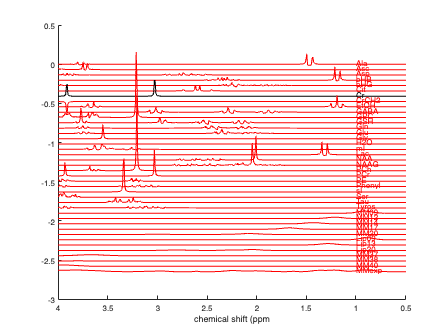

jobFile = fullfile(pathOsprey, 'exampledata', 'sdat', 'UnEdited', 'jobSDAT.m');

diary logfile.txt;
[gLCM] = OspreyJob(jobFile, 0, '11');
[gLCM] = OspreyLoad(gLCM);
[gLCM] = OspreyProcess(gLCM);

## 1 Collecting everything we need for the fit

We'll try and set up a fit model here now. Let's collect everything that we need.

In parallel, I will develop the class `FitObject` along, which will hold the actual properties and methods that the FitObject will consist of.


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Current plot held


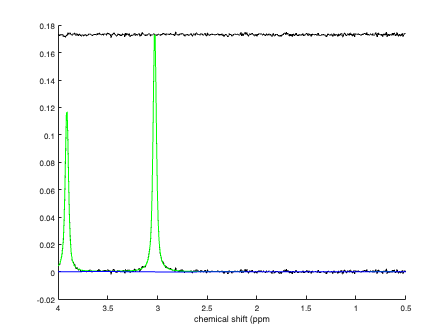

% Initialize the conventional OspreyFit:
gLCM = osp_fitInitialise(gLCM);

% Grab data
dataToFit = gLCM.processed.metab{1};                       % HZ new naming conventions 

% Grab basis set

Iter     1, f(x) = 4.848740e-04, ||grad||_infty = 9.87e-03


Current plot held


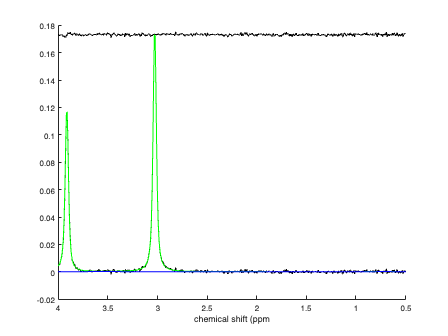

% Load the specified basis set or the user basis set file

basisSet = load(gLCM.opts.fit.basisSetFile);
basisSet = basisSet.BASIS;
basisSet = osp_recalculate_basis_specs(basisSet)            % HZ re-calculate specs

% 
basisSet = fit_sortBasisSet(basisSet);

## 2 Set up the FitObject

In this step, we'll initialize the FitObject by passing the data, basis set, and initial options.

% Create the spline basis functions for the given resolution, fit range,
% and knot spacing parameter.
opts.dkntmn             = 0.5; % minimum spacing between two neighboring spline knots
opts.optimDomain        = 'FD'; % do the least-squares optimization in the frequency domain
opts.optimSignalPart    = 'R'; % do the least-squares optimization over the real part of the spectrum
opts.optimFreqFitRange  = gLCM.opts.fit.range; % set the frequency-domain fit range to the fit range specified in the Osprey container

% Create an instance of the class
letsFitThis = FitObject(dataToFit, basisSet, opts);

Let's now decide which metabolites we want to exclude from the fit - by default, every signal in the basis set will be included in the fit.

% letsFitThis.excludeBasisFunctionFromFit({'Ala', 'bHB', 'bHG', 'Cit', 'Phenyl', 'Ser', 'Tyros', 'MMexp', 'MM37', 'MM37', 'MM38', 'MM40'}); 
letsFitThis.excludeBasisFunctionFromFit({'Ala','Asc','Asp','CrCH2','EtOH', 'bHB', 'bHG', 'Cit', 'GABA', 'GPC', 'Phenyl',...
                                          'GSH', 'Gln', 'Glu', 'Gly', 'H2O', 'mI', 'Lac', 'NAA', 'NAAG', 'PCh', 'PCr', 'PE', ...
                                          'sI', 'Tau', 'Ser', 'Tyros', 'MMexp','MM09', 'MM12', 'MM14','MM17', 'MM20', 'Lip09', ...
                                          'Lip13', 'Lip20', 'MM37', 'MM37', 'MM38', 'MM40'});
letsFitThis.plotBasisSet;

## 4 Fitting

### 4a Initial fitting

Once we have settled on our data, basis set, and fit options, we can start doing the actual fitting.

% Let's first start by initializing the fit parameters with a really coarse
% fit.
[ph0, gaussLB, lorentzLB, freqShift, metAmpl, baseAmpl] = letsFitThis.initFit;
letsFitThis.plotInitFit;

## 4b Complete fit

Now, we will do the actual fit.

letsFitThis.createModel;
letsFitThis.plotFit;

### 4.1 CRLB

## 5 Fitting water

Let's try and see whether we can fit water!

dataToFitWater = gLCM.processed.ref{1};

% Create the spline basis functions for the given resolution, fit range,
% and knot spacing parameter.
optsWater.dkntmn             = 2; % large knot spacing to force flat baseline
optsWater.optimDomain        = 'FD'; % do the least-squares optimization in the frequency domain
optsWater.optimSignalPart    = 'R'; % do the least-squares optimization over the real part of the spectrum
optsWater.optimFreqFitRange  = [0 8]; % big water fit range

% Create another instance of the class
letsFitWater = FitObject(dataToFitWater, basisSet, optsWater);

% Exclude all basis functions
letsFitWater.excludeBasisFunctionFromFit('all');
% Include only water
letsFitWater.includeBasisFunctionInFit('H2O');
% Run initial fit
[ph0W, gaussLBW, lorentzLBW, freqShiftW, metAmplW, baseAmplW] = letsFitWater.initFit;
% Plot initial fit
letsFitWater.plotInitFit;
letsFitWater.createModel;
letsFitWater.plotFit;